clear all

load 'C:\SortingFolder\HIP\NormalizedIndexesTable.mat';
load 'C:\SortingFolder\HIP\SignificanceWindowTable.mat'; %The matrix obtained from the fuction ExtractMatFiles.m

rangoY = [0 50]; % Y-axis range

% Significance
n= 1;
for i = 1: size(SignificanceWindowTable,1)
    if (SignificanceWindowTable.SignificanceDEV1(i,1) + SignificanceWindowTable.SignificanceDEV2(i,1)) > 1
        SIscatterIndx(n,1)=i;
        n = n + 1;
    end
 end

%SI
figure
%Create histogram
scatter(NormalizedIndexesTable.SI1(SIscatterIndx,1),NormalizedIndexesTable.SI2(SIscatterIndx,1),'filled', 'MarkerFaceColor','#990033');
xlim([-1 1]);
ylim([-1 1]);
title('SI CA1');
xlabel('SI F1');
ylabel('SI F2');

%Calculating the mean and error
SI_Mean = mean([NormalizedIndexesTable.SI1(SIscatterIndx,1);NormalizedIndexesTable.SI2(SIscatterIndx,1)],"omitnan")

SI_Mean = 0.0540

SI_std = std([NormalizedIndexesTable.SI1(SIscatterIndx,1);NormalizedIndexesTable.SI2(SIscatterIndx,1)],"omitnan");
err_SI = SI_std / sqrt((size([NormalizedIndexesTable.SI1(SIscatterIndx,1);NormalizedIndexesTable.SI2(SIscatterIndx,1)],1))*2)

err_SI = 0.0127

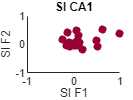


%Save figure
cd 'C:\SortingFolder\HIP\SI'
saveas(gcf,'SI.pdf');
saveas(gcf,'SI.tif');

saveas(gcf,'SI.fig');

% Significance SI Histogram
n= 1;
m= 1;
for i = 1: size(SignificanceWindowTable,1)
    if SignificanceWindowTable.SignificanceDEV1(i,1) > 0
        SI1HistIndx(n,1)=i;
        n = n + 1;
    end
    if SignificanceWindowTable.SignificanceDEV2(i,1) > 0
        SI2HistIndx(m,1)=i;
        m = m + 1;
    end 
 end

% SI
figure
%Create histogram
histogram([NormalizedIndexesTable.SI1(SI1HistIndx,1);NormalizedIndexesTable.SI2(SI2HistIndx,1)],'BinWidth',0.1, 'FaceColor','#990033','FaceAlpha',1);
xlim([-1 1]);
ylim([0 50]);
xline(0,'LineWidth',2);
title('SI');
xlabel('SI index');
ylabel('repetitions');

%Calculating the mean and error
SI_Mean = mean([NormalizedIndexesTable.SI1(SI1HistIndx,1);NormalizedIndexesTable.SI2(SI2HistIndx,1)],"omitnan")

SI_Mean = 0.0692

SI_std = std([NormalizedIndexesTable.SI1(SI1HistIndx,1);NormalizedIndexesTable.SI2(SI2HistIndx,1)],"omitnan");
err_SI = SI_std / sqrt((size([NormalizedIndexesTable.SI1(SI1HistIndx,1);NormalizedIndexesTable.SI2(SI2HistIndx,1)],1))*2)

err_SI = 0.0140

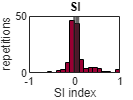

xline(SI_Mean,'LineWidth',2.5);

%Save figure
cd 'C:\SortingFolder\HIP\SI';
saveas(gcf,'SI_HIST.pdf');
saveas(gcf,'SI_HIST.tif');

saveas(gcf,'SI_HIST.fig');

% CSI
figure
%Create histogram
histogram(NormalizedIndexesTable.CSI(SIscatterIndx,1),'BinWidth',0.1, 'FaceColor','#990033','FaceAlpha',1);
xlim([-1 1]);
ylim(rangoY);
xline(0,'LineWidth',2);
title('CSI');
xlabel('CSI index');
ylabel('repetitions');

%Calculating the mean and error
CSI_Mean = mean(NormalizedIndexesTable.CSI(SIscatterIndx,1))

CSI_Mean = 0.0560

CSI_std = std(NormalizedIndexesTable.CSI(SIscatterIndx,1));
err_CSI = CSI_std / sqrt(size(NormalizedIndexesTable.CSI(SIscatterIndx,1),1))

err_CSI = 0.0198

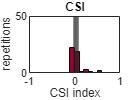

xline(CSI_Mean,'LineWidth',2.5);

%Save figure
cd 'C:\SortingFolder\HIP\CSI';
saveas(gcf,'CSI.pdf');
saveas(gcf,'CSI.tif');

saveas(gcf,'CSI.fig');

% iMM
iMMcasc = cat(1,NormalizedIndexesTable.iMM1ca(SI1HistIndx,1),NormalizedIndexesTable.iMM2cd(SI2HistIndx,1));
figure
%Create histogram
histogram(iMMcasc,'BinWidth',0.1,'FaceColor','#EA005F','FaceAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iMM');
xlabel('iMM index');
ylabel('repetitions');

%Calculating the mean and error
iMMcasc_Mean = nanmean(iMMcasc)

iMMcasc_Mean = 0.0667

iMMcasc_std = nanstd(iMMcasc);
err_iMMcasc = iMMcasc_std / sqrt(size(iMMcasc,1))

err_iMMcasc = 0.0200

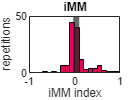

xline(iMMcasc_Mean,'LineWidth',2.5);

%Save figure
PathiMM = 'C:\SortingFolder\HIP\iMM';
cd (PathiMM);
saveas(gcf,'iMM.pdf');
saveas(gcf,'iMM.tif');

saveas(gcf,'iMM.fig');

% iPE CA1
iPEcasc = cat(1,NormalizedIndexesTable.iPE1ca(SI1HistIndx,1),NormalizedIndexesTable.iPE2cd(SI2HistIndx,1));
figure
%Create histogram
histogram(iPEcasc,'BinWidth',0.1,'FaceColor','#FF6600','FaceAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iPE');
xlabel('iPE index');
ylabel('repetitions');

%Calculating the mean and error
iPEcasc_Mean = nanmean(iPEcasc)

iPEcasc_Mean = 0.0679

iPEcasc_std = nanstd(iPEcasc);
err_iPEcasc = iPEcasc_std / sqrt(size(iPEcasc,1))

err_iPEcasc = 0.0181

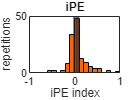

xline(iPEcasc_Mean,'LineWidth',2.5);

%Save figure
cd 'C:\SortingFolder\HIP\iPE';
saveas(gcf,'iPE.pdf');
saveas(gcf,'iPE.tif');

saveas(gcf,'iPE.fig');

% iRS CA1
iRScasc = cat(1,NormalizedIndexesTable.iRS1ca(SI1HistIndx,1),NormalizedIndexesTable.iRS2cd(SI2HistIndx,1));
figure
%Create histogram
histogram(iRScasc,'BinWidth',0.1,'FaceColor','#0099CC','FaceAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iRS');
xlabel('iRS index');
ylabel('repetitions');

%Calculating the mean and error
iRScasc_Mean = nanmean(iRScasc)

iRScasc_Mean = -0.0012

iRScasc_std = nanstd(iRScasc);
err_iRScasc = iRScasc_std / sqrt(size(iRScasc,1))

err_iRScasc = 0.0168

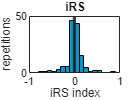

xline(iRScasc_Mean,'LineWidth',2.5);

%Save figure
cd 'C:\SortingFolder\HIP\iRS';
saveas(gcf,'iRS.pdf');
saveas(gcf,'iRS.tif');

saveas(gcf,'iRS.fig');